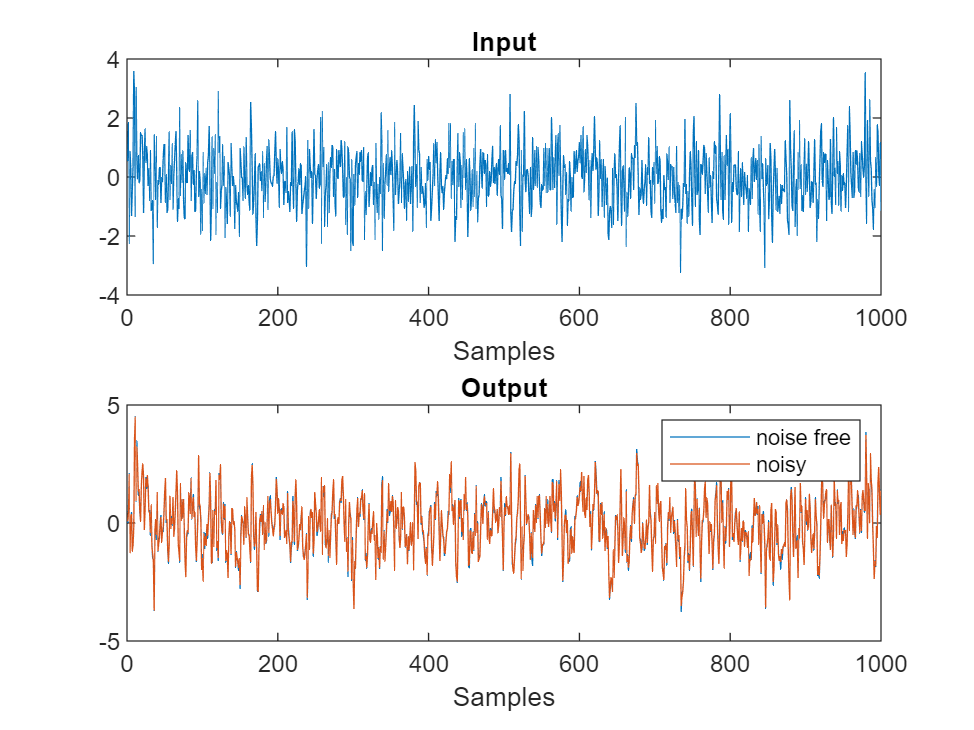

clear all
close all
clc

%% 1 - Model definition and data generation
% In this exercise we will work with the ARX defined as 
% y(t) = 0.5*y(t-1) + u(t-1) + e(t)

% True value of the parameters:
atrue = 0.5;
btrue = 1;

% We will work with simulated data, hence let's generate the data:
% (For a real SysID problem, data are not simulated but they are real, there is no model generating them, they come from the true system)
N = 1000; % number of data we want to generate

% Input: we will use a Gaussian signal as input:
u = randn(N,1); % white noise, std = 1
% Output: let's compute the output of the model (noise-free for now)
y = zeros(N,1);
for t = 2:N % zero initial condition
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%% Write your code here %%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    y(t) = atrue * y(t-1) + btrue*u(t-1);
end

% The output generated is noise-free, to be more realistic let's add some noise:
noise_std = 0.1;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%% Write your code here %%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
eG = noise_std*randn(N,1);

% Add the noise to the output
yn = y + eG;

% Let's plot the data (1 output realization)
figure(1); clf;
subplot(2,1,1)
plot(u)
title('Input')
xlabel('Samples')
subplot(2,1,2)
plot(y)
hold on
plot(yn)
legend('noise free','noisy')
title('Output')
xlabel('Samples')

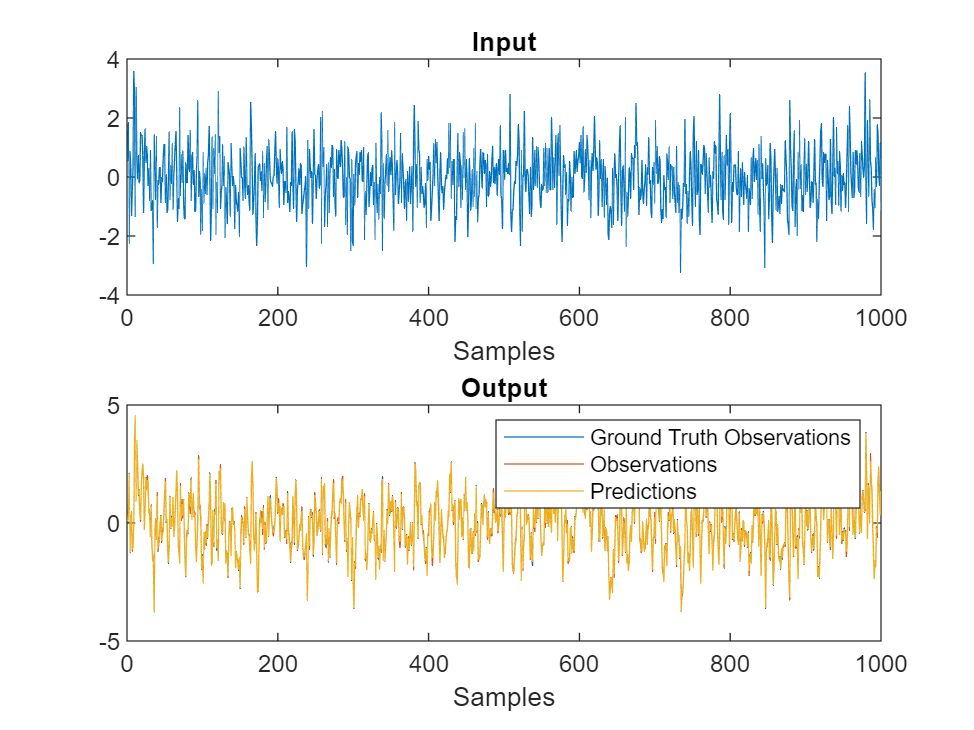

%%%%%%%%%%%%% Optional %%%%%%%%%%%%%%%%%%
% System was defined as 
% y(t) = 0.5*y(t-1) + u(t-1) + e(t)
% Assume we estimated the parameters, acquired the following model with
% correct parameters:
% y_hat(t) = 0.5*y(t-1) + u(t-1)
% Fill in the predictions then plot the results with yn and y_hat
y_hat = zeros(N,1);
y_hat(1) = yn(1);
for t = 2:N % Note, you are going to use observed y, i.e., noisy
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%% Write your code here %%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    y_hat(t) = 0.5*yn(t-1)+1*u(t-1);
end

% Add Plotting Code here
figure(2); clf;
subplot(2,1,1)
plot(u)
title('Input')
xlabel('Samples')
subplot(2,1,2)
plot(y)
hold on
plot(yn)
hold on
plot(y_hat)
legend('Ground Truth Observations','Observations','Predictions')
title('Output')
xlabel('Samples')

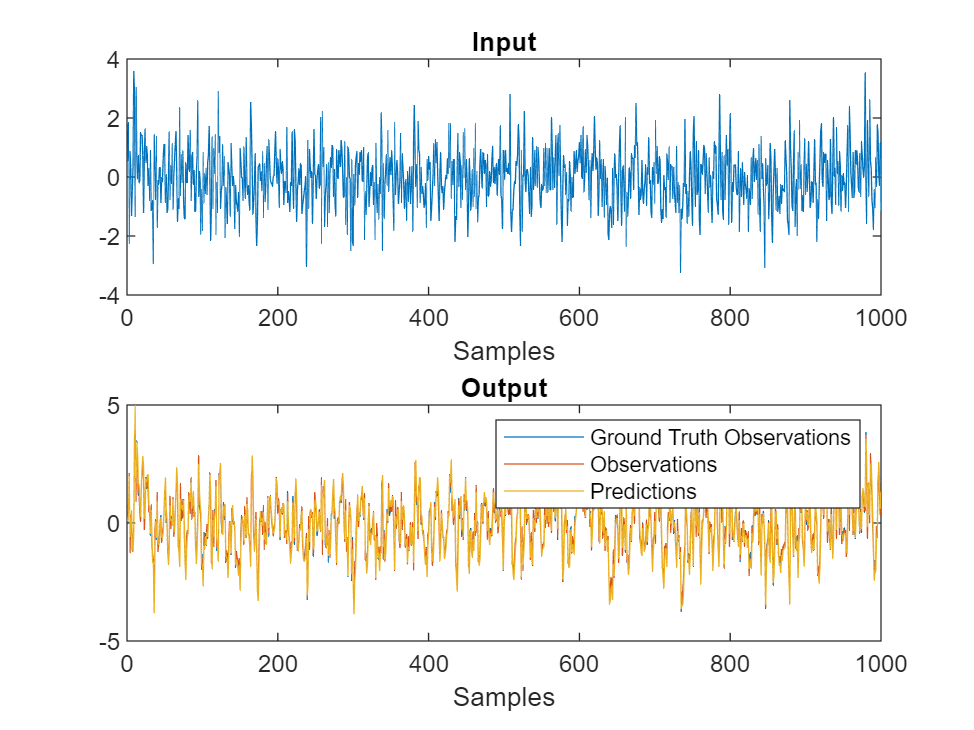

% Assume we estimated the parameters, acquired the following model with
% slightly wrong parameters:
% y_hat(t) = 0.7 y(t-1) + 0.9 u(t-1)
% Fill in the predictions then plot the results with yn and y_hat
y_hat = zeros(N,1);
y_hat(1) = yn(1);
for t = 2:N % Note, you are going to use observed y, i.e., noisy
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%% Write your code here %%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    y_hat(t) = 0.7*yn(t-1)+0.9*u(t-1);
end

% Add Plotting Code here
figure(3); clf;
subplot(2,1,1)
plot(u)
title('Input')
xlabel('Samples')
subplot(2,1,2)
plot(y)
hold on
plot(yn)
hold on
plot(y_hat)
legend('Ground Truth Observations','Observations','Predictions')
title('Output')
xlabel('Samples')

%% 2 - Identification using Least-Squares formula

% Now we do some identification!
% First of all let's split the data in estimation and validation sets
% (half and half)
uest = u(1:N/2);
yest = yn(1:N/2);
uval = u(N/2+1:end);
yval = yn(N/2+1:end);

% As model for identification we will use the 1-step-ahead predictor of
% ARX, which, as we know, is linear in the parameters.
% Hence, first let's write this predictor as a linear regression, in the
% form: y(t) = phi(t)*Theta
% where Theta is the parameter vector and phi(t) the regression vector.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%% With pen and paper, write the predictor in that form %%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Now that we have the predictor in the y(t) = phi(t)*Theta form, we can
% derive the vector form as well: Y = H*Theta, where, now Y is a vector and
% H is matrix.

% Let's build the matrix H:
H = zeros(N/2,2); % The matrix has N/2 rows (time instants), 2 columns (2 parameters)
H(1,:) = [0 0]; % Initial value
for i=2:N/2
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%% Write your code here %%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    H(i,:) = [yest(i-1), uest(i-1)];
end

% This vector form of the predictor is useful for deriving the least
% squares estimate of Theta

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%% With pen and paper, write the LS estimate of Theta in %%%%%%%%%%%%
%%%%%% terms of H and y %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Write the expression in code as well, so we get our estimate!
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%% Write your code here %%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
th = inv(H'*H)*H'*yest;

% th should be be a vector with two elements, estimated value for a and
% estimate value for b. Let's pick this two elements separetely:
ahat = th(1)

ahat = 0.5012

bhat = th(2)

bhat = 0.9962

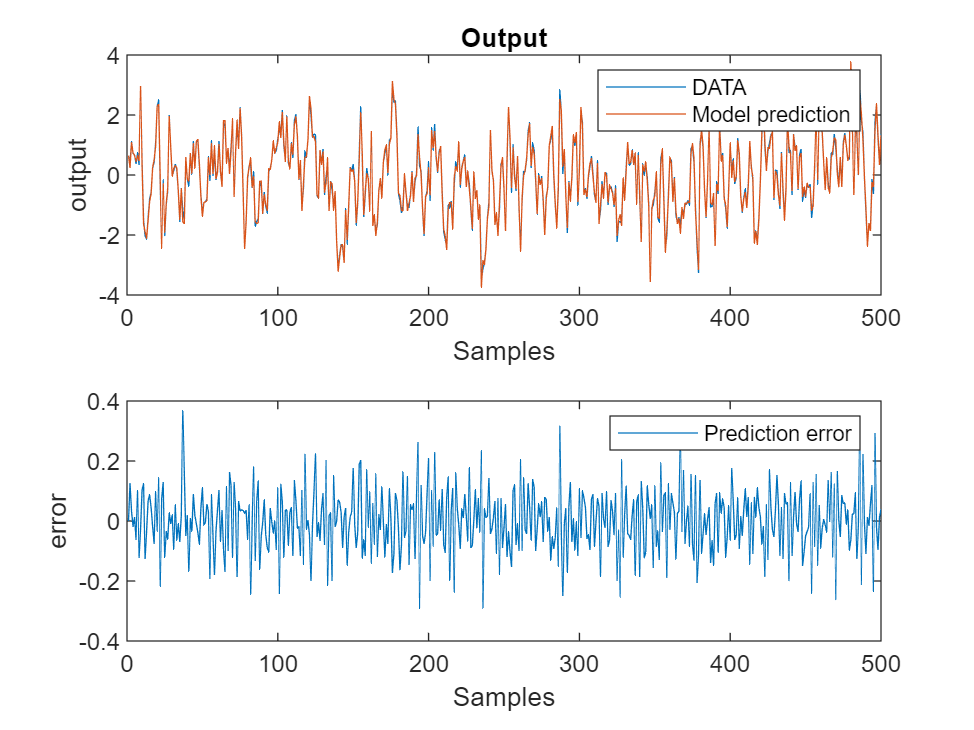

%% 3 - Prediction
% Let's now use the model we found to predict the output!
% Using validation data (or estimation data, just for a check)

NN = N/2;
% Let's redefine the data variables so it will be easy to switch from
% validation to estimation sets.
yn = yval;
un = uval;
% yn = yest; 
% un  = uest;

% Let's do prediction first, write your code for 1-step-ahead predictor
ypred = zeros(NN,1); % that's the vector where we will store the predicted output
ypred(1) = yn(1); % initial output is known
for i=2:NN
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%% Write your code here %%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % use the variables yn and un.
    ypred(i) = ahat*yn(i-1) + bhat*un(i-1);
end

% Once we have the predicted output we can compute the least-squares error with the true data
predERROR = yn-ypred;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%% Write your code here %%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
predRMSE  = rms(predERROR);
    
% plot DATA vs MODEL prediction
figure(2); clf;
subplot(2,1,1)
plot(yn)
hold on
plot(ypred)
legend('DATA','Model prediction')
title('Output')
xlabel('Samples')
ylabel('output')
subplot(2,1,2)
plot(predERROR)
legend('Prediction error')
xlabel('Samples')
ylabel('error')

disp(['Prediction RMS error is: ' num2str(predRMSE)])

Prediction RMS error is: 0.10706


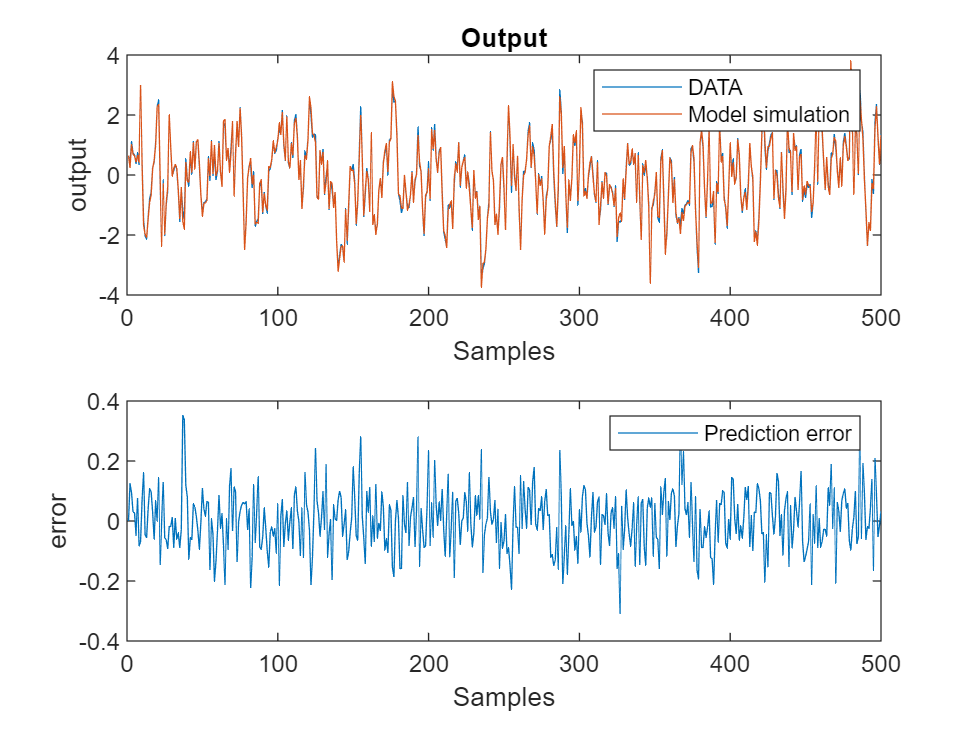

%% 4 - Simulation
ysim = zeros(NN,1); % that's the vector where we will store the simulated output
ysim(1) = yn(1); % initial output is known
% Write the code for simulation
for i=2:NN 
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%% Write your code here %%%%%%%%%%%%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    ysim(i) = ahat*ysim(i-1) + bhat*un(i-1);
end

% Compare with real data and compute least-squares error
simERROR = yn-ysim;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%% Write your code here %%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
simRMSE = rms(simERROR);

% plot DATA vs MODEL prediction
figure(3); clf;
subplot(2,1,1)
plot(yn)
hold on
plot(ysim)
legend('DATA','Model simulation')
title('Output')
xlabel('Samples')
ylabel('output')
subplot(2,1,2)
plot(simERROR)
legend('Prediction error')
xlabel('Samples')
ylabel('error')

 
disp(['Simulation RMS error is: ' num2str(simRMSE)])

Simulation RMS error is: 0.098927
